NoisedImage = imread('D:/Matlab/project/图像处理/NoisedImage.tif');
imshow(NoisedImage);
NoisedImage = im2double(NoisedImage)

NoisedImage =     1.0000    0.9725    0.9686    0.9373    1.0000    0.7725    1.0000    1.0000    1.0000    0.8824    1.0000    1.0000    0.6392    0.9882    1.0000    1.0000    0.9569    0.9765    0.8627    1.0000    0.8863    1.0000    1.0000    1.0000    1.0000    1.0000    0.8980    0.9294    0.8824    0.9059    0.9373    0.9059    0.9647    1.0000    0.8863    1.0000    0.9686    0.9569    0.8549    0.8706    1.0000    1.0000    1.0000    0.9961    1.0000    0.9216    0.9373    0.9843    0.9216    0.9529
    0.9765    1.0000    0.9451    1.0000    0.9137    0.9765    0.9608    1.0000    0.9373    0.9176    1.0000    1.0000    0.8784    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9608    0.9804    0.8392    1.0000    1.0000    0.9882    0.9412    0.9137    0.8431    0.9843    0.9882    0.9686    1.0000    0.9725    1.0000    1.0000    0.9569    0.8392    1.0000    0.6471    1.0000    1.0000    1.0000    0.8902    1.0000    1.0000    0.9216    0.9882    1.0000    0

[M,N] = size(NoisedImage);
% 二维快速傅里叶变换
F = fft2(NoisedImage);
S = abs(F)

S = 	1.0e+05 *

    1.2307    0.0529    0.0576    0.0614    0.0395    0.0524    0.0331    0.0225    0.0158    0.0270    0.0384    0.0226    0.0154    0.0073    0.0111    0.0146    0.0048    0.0165    0.0197    0.0207    0.0176    0.0141    0.0255    0.0039    0.0040    0.0051    0.0088    0.0042    0.0046    0.0024    0.0042    0.0057    0.0055    0.0024    0.0020    0.0015    0.0026    0.0030    0.0032    0.0029    0.0052    0.0042    0.0161    0.0012    0.0123    0.0018    0.0019    0.0021    0.0063    0.0019
    0.0742    0.0387    0.0125    0.0320    0.0309    0.0214    0.0154    0.0367    0.0094    0.0270    0.0330    0.0245    0.0290    0.0107    0.0023    0.0082    0.0048    0.0041    0.0036    0.0170    0.0131    0.0055    0.0212    0.0075    0.0011    0.0041    0.0025    0.0027    0.0014    0.0038    0.0015    0.0037    0.0047    0.0062    0.0005    0.0016    0.0026    0.0016    0.0035    0.0043    0.0004    0.0012    0.0043    0.0176    0.0078    0.0110    0.0030    0.0021   

imshow(F, [ ]);

% fftshift将零频分量移动到中心
Fc = fftshift(F)

Fc = 	1.0e+05 *

   0.0003 + 0.0000i   0.0002 + 0.0004i   0.0000 + 0.0002i  -0.0003 + 0.0000i   0.0003 + 0.0000i  -0.0002 - 0.0004i  -0.0006 - 0.0001i   0.0001 - 0.0002i   0.0001 - 0.0005i   0.0002 - 0.0000i   0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0001 + 0.0001i   0.0002 - 0.0000i   0.0004 - 0.0003i  -0.0000 + 0.0001i   0.0002 + 0.0000i  -0.0000 + 0.0004i   0.0002 - 0.0002i  -0.0004 + 0.0001i  -0.0003 + 0.0001i   0.0001 + 0.0002i   0.0000 + 0.0003i  -0.0002 + 0.0000i   0.0001 - 0.0003i  -0.0000 - 0.0001i  -0.0002 - 0.0000i   0.0002 - 0.0002i   0.0002 - 0.0002i   0.0003 + 0.0003i   0.0002 + 0.0002i   0.0002 + 0.0001i  -0.0003 - 0.0001i   0.0001 - 0.0000i  -0.0000 - 0.0006i  -0.0003 + 0.0003i   0.0002 - 0.0005i   0.0000 - 0.0000i   0.0002 + 0.0006i  -0.0001 - 0.0002i   0.0000 + 0.0001i  -0.0001 - 0.0002i   0.0002 - 0.0000i   0.0001 + 0.0002i   0.0004 - 0.0003i  -0.0003 + 0.0001i  -0.0003 + 0.0000i   0.0003 - 0.0003i   0.0001 + 0.0003i  -0.0001 + 0.0001i
  -0.0001 - 0.0004i   0.0003 + 0

imshow(abs(Fc), [ ]);
S2 = log(1+abs(Fc))

S2 =     3.5463    3.7578    2.8281    3.3455    3.5071    3.6899    4.1628    3.1859    3.8857    3.0391    2.7602    2.7015    2.4932    3.2010    3.8836    2.2262    2.9851    3.7871    3.3663    3.8170    3.4696    3.3962    3.4518    3.0627    3.4633    2.0085    2.9910    3.3845    3.3916    3.8154    3.4043    3.0068    3.3180    2.0465    4.1053    3.8160    3.9753    1.4315    4.1030    3.0463    2.1657    3.1236    3.2610    3.3698    3.8870    3.2909    3.4806    3.7056    3.5991    2.9443
    3.7800    3.4061    4.0054    3.6600    3.4131    3.2121    3.9777    3.2095    3.3551    3.9348    3.2427    3.6097    3.8673    2.8779    2.9101    3.2917    4.3180    2.8940    3.7198    3.4308    3.6467    2.5902    3.6593    2.4815    3.5146    2.6967    2.9259    3.1728    4.1066    3.0082    4.1061    3.4432    2.1798    3.3770    3.4315    3.6742    2.0143    2.1809    3.6678    2.7819    1.9683    3.9496    2.6971    3.8180    2.8770    3.3969    2.9900    3.4755    3.3776    

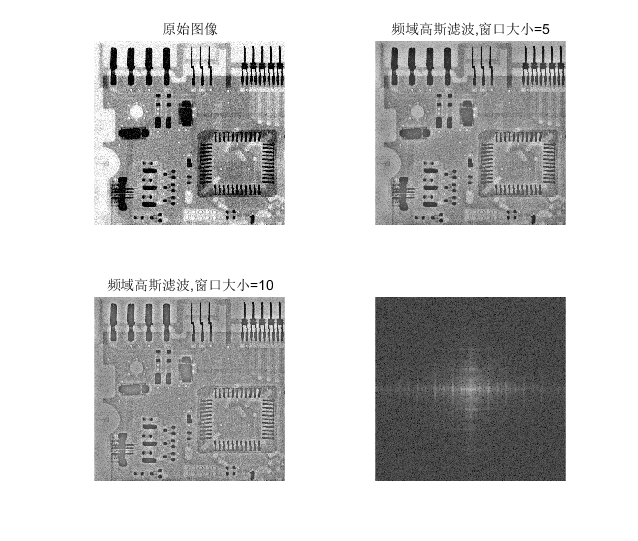

imshow(S2,[ ])

sig1 = 5

sig1 = 5

H1 = hpfilter('gaussian',M,N,sig1)

H1 =          0    0.0198    0.0769    0.1647    0.2739    0.3935    0.5132    0.6247    0.7220    0.8021    0.8647    0.9111    0.9439    0.9660    0.9802    0.9889    0.9940    0.9969    0.9985    0.9993    0.9997    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0198    0.0392    0.0952    0.1813    0.2882    0.4055    0.5229    0.6321    0.7275    0.8060    0.8673    0.9128    0.9450    0.9666    0.9806    0.9891    0.9941    0.9970    0.9985    0.9993    0.9997    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    

sig2 = 10

sig2 = 10

H2 = hpfilter('gaussian',M,N,sig2)

H2 =          0    0.0050    0.0198    0.0440    0.0769    0.1175    0.1647    0.2173    0.2739    0.3330    0.3935    0.4539    0.5132    0.5704    0.6247    0.6753    0.7220    0.7643    0.8021    0.8355    0.8647    0.8897    0.9111    0.9290    0.9439    0.9561    0.9660    0.9739    0.9802    0.9851    0.9889    0.9918    0.9940    0.9957    0.9969    0.9978    0.9985    0.9989    0.9993    0.9995    0.9997    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0050    0.0100    0.0247    0.0488    0.0815    0.1219    0.1689    0.2212    0.2775    0.3363    0.3965    0.4566    0.5157    0.5726    0.6266    0.6770    0.7233    0.7654    0.8031    0.8363    0.8653    0.8903    0.9115    0.9293    0.9441    0.9563    0.9661    0.9740    0.9803    0.9852    0.9889    0.9919    0.9941    0.9957    0.9969    0.9978    0.9985    0.9989    0.9993    0.9995    0.9997    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    

sig3 = 30

sig3 = 30

H3 = hpfilter('gaussian',M,N,sig3)

H3 =          0    0.0006    0.0022    0.0050    0.0088    0.0138    0.0198    0.0269    0.0349    0.0440    0.0540    0.0650    0.0769    0.0896    0.1032    0.1175    0.1326    0.1483    0.1647    0.1817    0.1993    0.2173    0.2358    0.2546    0.2739    0.2934    0.3131    0.3330    0.3531    0.3733    0.3935    0.4137    0.4338    0.4539    0.4739    0.4937    0.5132    0.5326    0.5517    0.5704    0.5889    0.6070    0.6247    0.6420    0.6589    0.6753    0.6914    0.7069    0.7220    0.7365
    0.0006    0.0011    0.0028    0.0055    0.0094    0.0143    0.0203    0.0274    0.0355    0.0445    0.0546    0.0655    0.0774    0.0901    0.1037    0.1180    0.1331    0.1488    0.1652    0.1822    0.1997    0.2177    0.2362    0.2551    0.2743    0.2937    0.3135    0.3334    0.3535    0.3736    0.3938    0.4140    0.4342    0.4542    0.4742    0.4939    0.5135    0.5329    0.5519    0.5707    0.5891    0.6072    0.6249    0.6422    0.6591    0.6755    0.6915    0.7071    0.7221    

G1 = H1.*F

G1 = 	1.0e+03 *

   0.0000 + 0.0000i   0.1032 - 0.0177i   0.3977 - 0.1950i   0.8222 - 0.5895i   0.8082 - 0.7195i   0.3351 - 2.0359i   0.8074 - 1.4929i  -0.7693 - 1.1795i   1.0939 - 0.3176i   2.1644 + 0.0755i  -2.0496 - 2.6168i  -1.4822 + 1.4263i   1.4179 + 0.2989i   0.2059 - 0.6703i   0.0533 - 1.0859i   0.4314 - 1.3780i  -0.3377 + 0.3345i   1.1313 - 1.1984i  -1.4919 - 1.2784i   0.7546 - 1.9229i  -0.3875 - 1.7143i  -0.3525 - 1.3674i   1.2354 + 2.2309i   0.3900 - 0.0592i   0.3890 + 0.0790i   0.5056 + 0.0315i   0.3868 - 0.7959i   0.0937 + 0.4062i   0.1821 - 0.4183i   0.1698 - 0.1721i  -0.2192 - 0.3534i  -0.2521 - 0.5150i   0.5354 - 0.1091i  -0.2401 - 0.0377i  -0.1900 - 0.0683i  -0.0997 + 0.1075i  -0.2495 - 0.0600i   0.2948 + 0.0213i  -0.1123 - 0.3009i   0.1989 + 0.2147i   0.2963 - 0.4234i   0.0854 - 0.4115i   1.5137 - 0.5489i  -0.1191 + 0.0112i  -1.1761 + 0.3516i   0.1708 - 0.0627i  -0.1932 - 0.0059i   0.0158 + 0.2073i   0.6104 + 0.1578i   0.1723 + 0.0711i
   0.1343 - 0.0598i  -0.1048 + 0

G2 = H2.*F

G2 = 	1.0e+03 *

   0.0000 + 0.0000i   0.0260 - 0.0045i   0.1024 - 0.0502i   0.2196 - 0.1575i   0.2269 - 0.2020i   0.1001 - 0.6080i   0.2591 - 0.4791i  -0.2676 - 0.4103i   0.4149 - 0.1205i   0.8986 + 0.0314i  -0.9327 - 1.1908i  -0.7385 + 0.7106i   0.7710 + 0.1625i   0.1216 - 0.3959i   0.0339 - 0.6921i   0.2946 - 0.9411i  -0.2453 + 0.2429i   0.8673 - 0.9188i  -1.1985 - 1.0270i   0.6309 - 1.6078i  -0.3352 - 1.4828i  -0.3137 - 1.2168i   1.1257 + 2.0327i   0.3623 - 0.0550i   0.3671 + 0.0745i   0.4834 + 0.0301i   0.3736 - 0.7688i   0.0913 + 0.3956i   0.1785 - 0.4100i   0.1673 - 0.1696i  -0.2168 - 0.3495i  -0.2500 - 0.5108i   0.5322 - 0.1085i  -0.2390 - 0.0375i  -0.1894 - 0.0681i  -0.0995 + 0.1073i  -0.2491 - 0.0599i   0.2945 + 0.0212i  -0.1123 - 0.3006i   0.1988 + 0.2146i   0.2962 - 0.4233i   0.0853 - 0.4115i   1.5134 - 0.5488i  -0.1191 + 0.0112i  -1.1760 + 0.3516i   0.1708 - 0.0627i  -0.1932 - 0.0059i   0.0158 + 0.2073i   0.6104 + 0.1578i   0.1723 + 0.0711i
   0.0338 - 0.0151i  -0.0266 + 0

G3 = H3.*F

G3 = 	1.0e+03 *

   0.0000 + 0.0000i   0.0029 - 0.0005i   0.0115 - 0.0056i   0.0249 - 0.0178i   0.0261 - 0.0233i   0.0117 - 0.0714i   0.0311 - 0.0576i  -0.0331 - 0.0507i   0.0529 - 0.0154i   0.1187 + 0.0041i  -0.1281 - 0.1635i  -0.1058 + 0.1018i   0.1155 + 0.0243i   0.0191 - 0.0622i   0.0056 - 0.1143i   0.0513 - 0.1637i  -0.0450 + 0.0446i   0.1683 - 0.1783i  -0.2461 - 0.2109i   0.1372 - 0.3497i  -0.0772 - 0.3417i  -0.0766 - 0.2972i   0.2913 + 0.5260i   0.0993 - 0.0151i   0.1065 + 0.0216i   0.1483 + 0.0092i   0.1211 - 0.2492i   0.0312 + 0.1353i   0.0643 - 0.1477i   0.0634 - 0.0642i  -0.0863 - 0.1391i  -0.1043 - 0.2130i   0.2323 - 0.0474i  -0.1090 - 0.0171i  -0.0900 - 0.0324i  -0.0492 + 0.0531i  -0.1281 - 0.0308i   0.1570 + 0.0113i  -0.0620 - 0.1660i   0.1135 + 0.1225i   0.1745 - 0.2493i   0.0518 - 0.2498i   0.9456 - 0.3429i  -0.0765 + 0.0072i  -0.7749 + 0.2317i   0.1153 - 0.0423i  -0.1336 - 0.0041i   0.0111 + 0.1466i   0.4407 + 0.1140i   0.1269 + 0.0524i
   0.0038 - 0.0017i  -0.0030 + 0

g1 = real(ifft2(G1)); %傅里叶逆变换
g2 = real(ifft2(G2)); %傅里叶逆变换
g3 = real(ifft2(G3)); %傅里叶逆变换

function H = lpfilter(type, M, N, D0, n)
%LPFILTER Computes frequency domain lowpass filters.
%   H = LPFILTER(TYPE, M, N, D0, n) creates the transfer function of
%   a lowpass filter, H, of the specified TYPE and size (M-by-N). To
%   view the filter as an image or mesh plot, it should be centered
%   using H = fftshift(H). 
%
%   Valid values for TYPE, D0, and n are:
%
%   'ideal'    Ideal lowpass filter with cutoff frequency D0. n need
%              not be supplied.  D0 must be positive.
%
%   'btw'      Butterworth lowpass filter of order n, and cutoff
%              D0.  The default value for n is 1.0.  D0 must be
%              positive.
%
%   'gaussian' Gaussian lowpass filter with cutoff (standard
%              deviation) D0.  n need not be supplied.  D0 must be
%              positive. 

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.8 $  $Date: 2004/11/04 22:33:16 $

% Use function dftuv to set up the meshgrid arrays needed for
% computing the required distances. 
[U, V] = dftuv(M, N);

% Compute the distances D(U, V).
D = sqrt(U.^2 + V.^2);

% Begin filter computations.
switch type
case 'ideal'
   H = double(D <= D0);
case 'btw'
   if nargin == 4
      n = 1;	
   end
   H = 1./(1 + (D./D0).^(2*n));
case 'gaussian'
   H = exp(-(D.^2)./(2*(D0^2)));
otherwise
   error('Unknown filter type.')
end
end

function H = hpfilter(type, M, N, D0, n)
%HPFILTER Computes frequency domain highpass filters.
%   H = HPFILTER(TYPE, M, N, D0, n) creates the transfer function of
%   a highpass filter, H, of the specified TYPE and size (M-by-N).
%   Valid values for TYPE, D0, and n are: 
%
%   'ideal'    Ideal highpass filter with cutoff frequency D0.  n
%              need not be supplied. D0 must be positive.
%
%   'btw'      Butterworth highpass filter of order n, and cutoff
%              D0.  The default value for n is 1.0. D0 must be
%              positive.
%
%   'gaussian' Gaussian highpass filter with cutoff (standard
%              deviation) D0. n need not be supplied. D0 must be
%              positive.

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.4 $  $Date: 2003/08/25 14:28:22 $

% The transfer function Hhp of a highpass filter is 1 - Hlp, 
% where Hlp is the transfer function of the corresponding lowpass 
% filter.  Thus, we can use function lpfilter to generate highpass 
% filters.

if nargin == 4
   n = 1; % Default value of n.
end

% Generate highpass filter.
Hlp = lpfilter(type, M, N, D0, n);
H = 1 - Hlp;
end

function [U, V] = dftuv(M, N)
%DFTUV Computes meshgrid frequency matrices.
%   [U, V] = DFTUV(M, N) computes meshgrid frequency matrices U and
%   V.  U and V are useful for computing frequency-domain filter
%   functions that can be used with DFTFILT.  U and V are both
%   M-by-N.

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.3 $  $Date: 2003/04/16 22:30:34 $

% Set up range of variables.
u = 0:(M - 1);
v = 0:(N - 1);

% Compute the indices for use in meshgrid.
idx = find(u > M/2);
u(idx) = u(idx) - M;
idy = find(v > N/2);
v(idy) = v(idy) - N;

% Compute the meshgrid arrays.
[V, U] = meshgrid(v, u);
end